%% ========== Setup ========== %%
% ===== Setup
clc; clear; close all;

% ===== Initial Value
ub = [5, 5];
lb = [0, 0];
x0 = [0, 0];

A = [1, 2];
b = 2;

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.020200e+00    9.700e-01    7.844e-01
    1       6    1.911435e+00    0.000e+00    6.991e-01    7.211e-01
    2       9    1.899152e+00    0.000e+00    1.001e-01    1.602e-01
    3      12    1.804761e+00    0.000e+00    2.149e-02    6.025e-02
    4      15    1.801042e+00    0.000e+00    1.136e-03    6.319e-03
    5      18    1.800011e+00    0.000e+00    1.071e-04    6.240e-04
    6      21    1.800010e+00    0.000e+00    1.000e-05    1.735e-05
    7      24    1.800000e+00    0.000e+00    9.750e-07    7.428e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

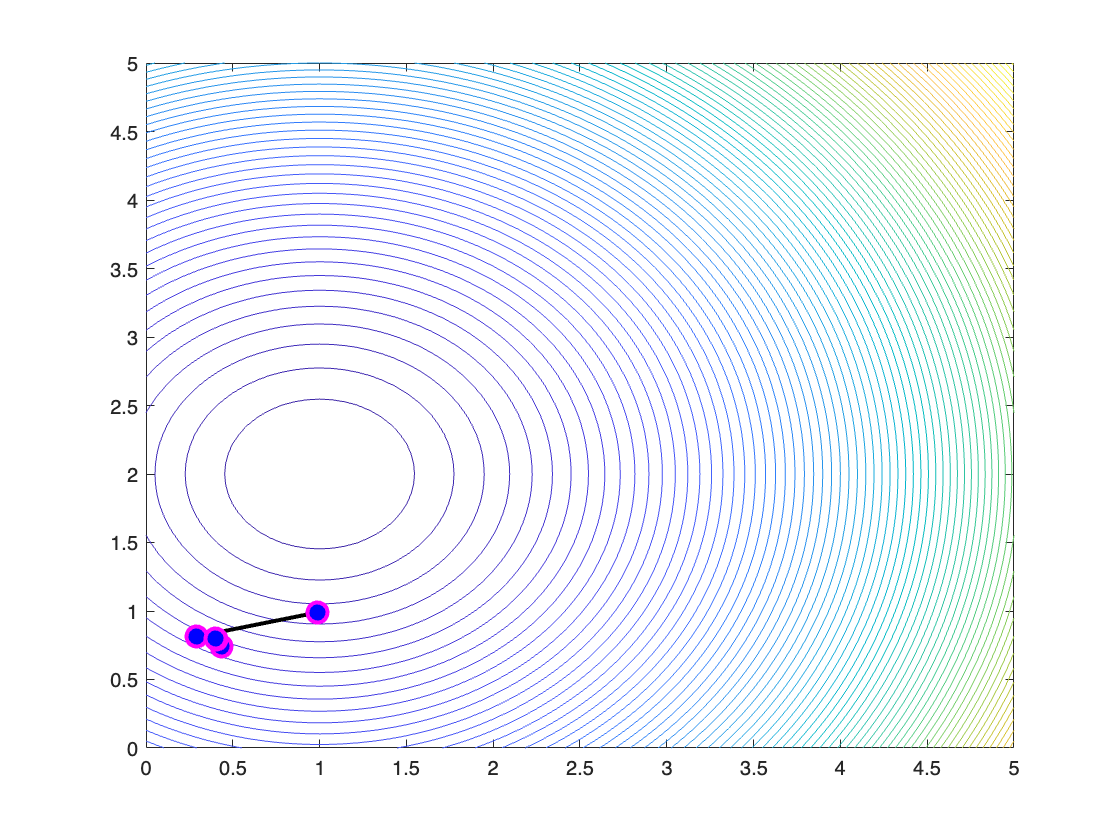

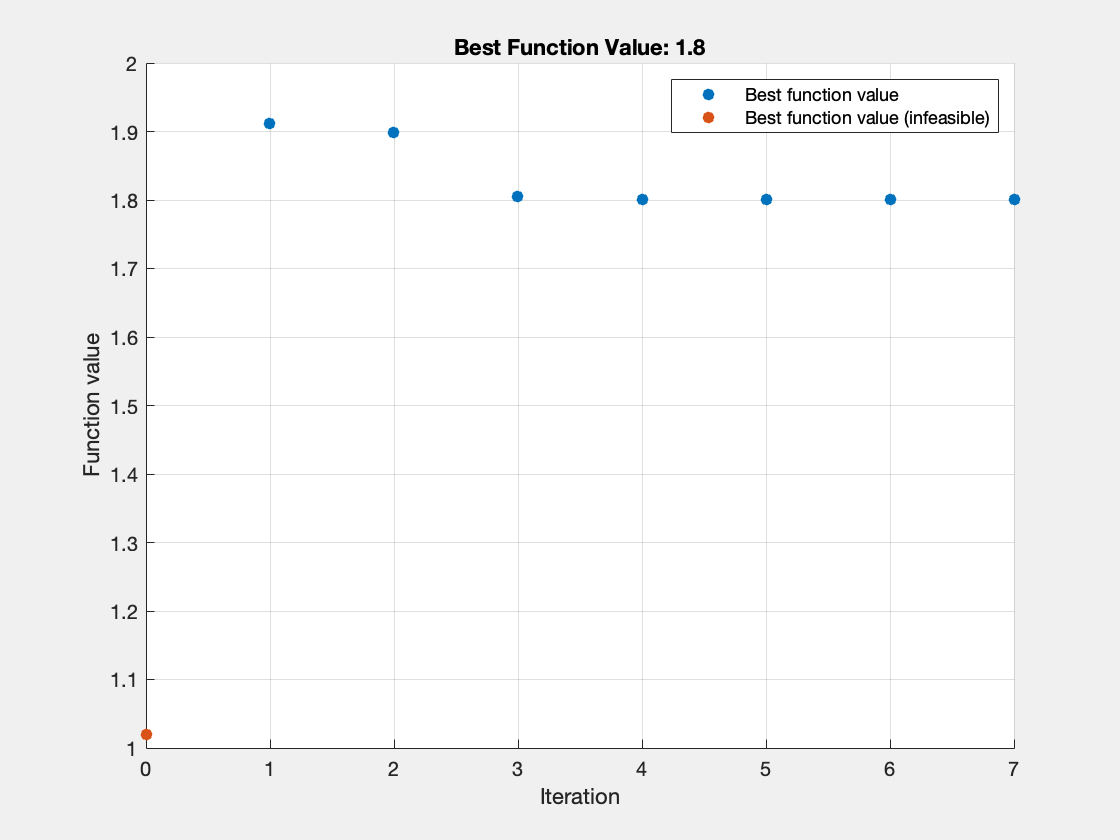

% Set nondefault solver options
options = optimoptions("fmincon","OutputFcn",@plotUpdate2,"Display","iter",...
    "PlotFcn","optimplotfvalconstr");

% Solve
[solution,objectiveValue] = fmincon(@objectiveFcn,x0,A,b,[],[],lb,ub,[],...
    options);


% Clear variables
clearvars options
function f = objectiveFcn(optimInput)
% Example:
% Minimize Rosenbrock's function
% f = 100*(y - x^2)^2 + (1 - x)^2

% Edit the lines below with your calculation
x = optimInput(1);
y = optimInput(2);
f = (x-1)^2 + (y-2)^2;
end
